% read in a default audio file
[s, Fs] = audioread('guitartune.wav');

epochs = 10;
var = 2e-5;

% filter order (idk what number we want)
L = 25; 

% get filter coeffs
[hb, ha] = cheby2(6, 30, 0.55)

hb =     0.1382    0.4319    0.7923    0.9526    0.7923    0.4319    0.1382


ha =     1.0000    0.5015    1.1616    0.5282    0.3628    0.1038    0.0196


mu = 0.001/((L+1)*var)

mu = 1.9231

% all eigenvalues are equal to var since R = var*I

rand_n = randn(size(s));
r = sqrt(var)*rand_n;
rf = filter(hb, ha, r)

rf =    -0.0008
   -0.0015
   -0.0006
    0.0009
    0.0027
    0.0033
    0.0020
   -0.0005
   -0.0021
   -0.0022


x = s + rf

x =    -0.0008
   -0.0015
   -0.0006
    0.0009
    0.0027
    0.0033
    0.0020
   -0.0005
   -0.0021
   -0.0022


% sound(x, Fs)

avg_noise = zeros(size(s));

for q = 1:epochs 
    y = zeros(size(s));
    e = zeros(size(s));
    w = zeros(1, L+1);

    for k = L+1:length(s)
        y(k) = w*r(k:-1:k-L);
        e(k) = x(k) - y(k);
        w = w + 2*mu*e(k)*r(k:-1:k-L).';
    end
    
    avg_noise = avg_noise + (s-e).^2;
end

avg_noise = avg_noise / epochs

avg_noise =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


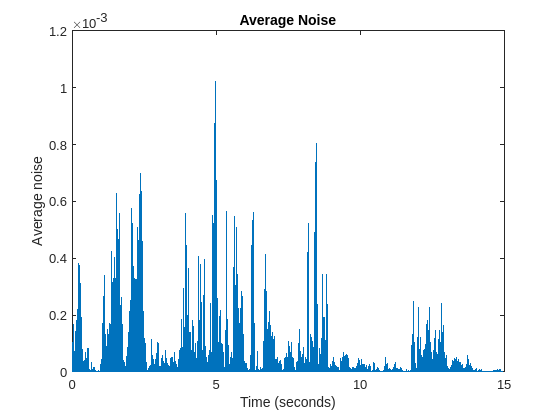

plot((0:length(s)-1)/Fs, avg_noise)
xlabel('Time (seconds)')
ylabel('Average noise')
title('Average Noise')

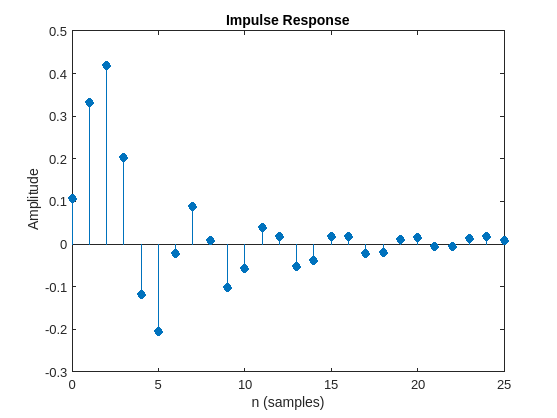

impz(w)

[H, w1] = freqz(hb,ha)

H =    1.0000 + 0.0000i
   1.0000 - 0.0076i
   0.9999 - 0.0151i
   0.9997 - 0.0227i
   0.9995 - 0.0303i
   0.9993 - 0.0378i
   0.9990 - 0.0454i
   0.9986 - 0.0530i
   0.9982 - 0.0605i
   0.9977 - 0.0681i


w1 =          0
    0.0061
    0.0123
    0.0184
    0.0245
    0.0307
    0.0368
    0.0430
    0.0491
    0.0552


H2 = freqz(w, 1, w1)

H2 =    0.6639 + 0.0000i
   0.6639 + 0.0015i
   0.6639 + 0.0031i
   0.6639 + 0.0049i
   0.6640 + 0.0067i
   0.6642 + 0.0088i
   0.6645 + 0.0112i
   0.6650 + 0.0138i
   0.6658 + 0.0167i
   0.6670 + 0.0199i


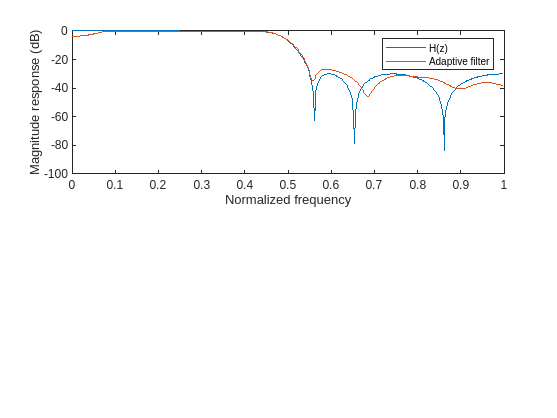

subplot(211)
plot(w1/pi, 20*log10(abs(H)))
hold on;
plot(w1/pi, 20*log10(abs(H2)))
xlabel('Normalized frequency')
ylabel('Magnitude response (dB)')
legend('H(z)', 'Adaptive filter')
hold off

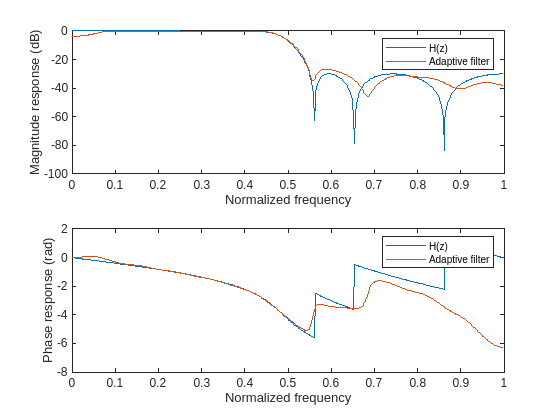

subplot(212)
plot(w1/pi, unwrap(angle(H)))
hold on;
plot(w1/pi, unwrap(angle(H2)))
xlabel('Normalized frequency')
ylabel('Phase response (rad)')
legend('H(z)', 'Adaptive filter')
hold off

sound(e, Fs)